# example for importance sampling of SRP (Cook–Torrance model)

モンテカルロ積分に使う乱数の数は `nMCintUni & nMCintImp`

`それを nMC `回行って平均と分散を計算し，plotする．（ややこしい）

clc
clear
cls

format long

## Monte-Carlo condition & pre-allocation

nMC = 100;

srpTrue = zeros(nMC, 3);
srpImp = zeros(nMC, 3);

## object

sat = readSC('flatPlate.obj', 1)

Reading Object file : flatPlate.obj
  % Blender v2.91.2 OBJ File: 'flatPlate.blend'
  %www.blender.org
Reading Material file : flatPlate.mtl
  % Blender MTL File: 'flatPlate.blend'
  % Material Count: 1
Finished Reading Material file
Finished Reading Object file


ans =      8     3


ans =     12     3


sat = フィールドをもつ struct :
    vertices: [8×3 double]
       faces: [12×3 double]
        area: [12×1 double]
         pos: [12×3 double]
      normal: [12×3 double]
          uu: [12×3 double]
          uv: [12×3 double]
         qlb: [12×4 double]
          Ca: [12×1 double]
          Cd: [12×1 double]
          Cs: [12×1 double]


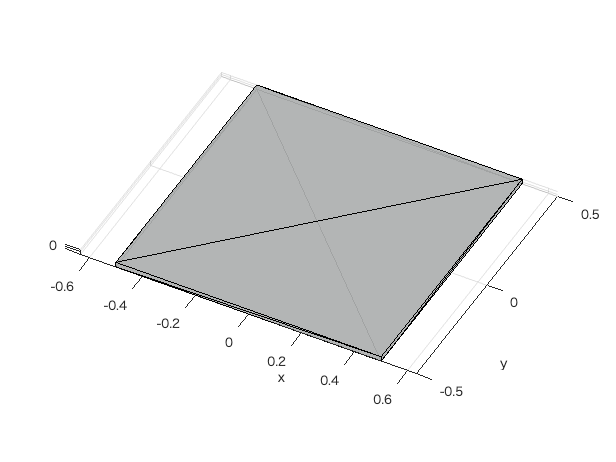

showSC(sat);


nFacet = size(sat.faces,1);
sat.rho = 0.5 .* ones(nFacet,1);
sat.F0 = 0.5 .* ones(nFacet,1);
sat.mCT = 0.45 .* ones(nFacet,1);

const = orbitConst;
d = au2km(1, const) * 10^3; % m
dAU = km2AU(d ./ 10^3, const); % AU
S0 = const.S0; % Solar constant, W/m^2
c = const.c; % light speed, m/s
coeff = -S0 / c / dAU^2;

## Cook–Torrance model

thetaI = deg2rad(35);
phiI = deg2rad(40);

sunB = [sin(thetaI)*cos(phiI), sin(thetaI)*sin(phiI), cos(thetaI)];
sunB = sunB ./ norm(sunB);

% Monte-Carlo integration condition
nMCintUni = [100,500, 1000, 5000, 10000, 50000, 100000];
% nMCintUni = 100:500:100000;
% nMCintUni = [10^3 10^4];

tic
for i = 1:length(nMCintUni)
    N = nMCintUni(i);
    for j = 1:nMC

## speuclar only, uniform distribution

        [~, ~, srpCs] = srpCTuni(sat, sunB, d, const, 'Beckmann', N);

        srpTrue(j,:) = srpCs;
    end
    stdTrue(i,:) = std(srpTrue);
    meanTrue(i,:) = mean(srpTrue);
end
toc

経過時間は 7.790050 秒です。


## importance sampling

% Monte-Carlo integration condition
nMCintImp = [10 1000];
nMCintImp = nMCintUni;

tic

#### transform to local frame

eAngle = acos(sat.normal(:,3));
eAxis = cross(repmat([0 0 1],nFacet,1), sat.normal) .* (eAngle > 1e-5) ...
    + repmat([0 0 1],nFacet,1) .* (eAngle < 1e-5) ...
    + repmat([1 0 0],nFacet,1) .* (eAngle > pi-1e-5); % normal vectorがほぼ[0 0 -1]のとき
eAxis = eAxis ./ vecnorm(eAxis, 2, 2);

% quaternion from body-fixed frame to local frame
qlb = [eAxis.*sin(eAngle/2), cos(eAngle/2)]; % nFacet x 4

% sun vector and normal vectors at local frame (normal vector is along z-axis)
sLocal = qRotation(4, repmat(sunB,nFacet,1), qlb); % nFacet x 3
nLocal = qRotation(4, sat.normal, qlb); % nFacet x 3

NS = sat.normal * sunB'; % nx1

for i = 1:length(nMCintImp)
    N = nMCintImp(i);
    for j = 1:nMC
        [~, ~, srpCs] = srpCT(sat, sunB, d, const, 'Beckmann', N);

        srpImp(j,:) = srpCs;
    end
    stdImp(i,:) = std(srpImp);
    meanImp(i,:) = mean(srpImp);
end

toc

経過時間は 3.613198 秒です。


## show FIgs

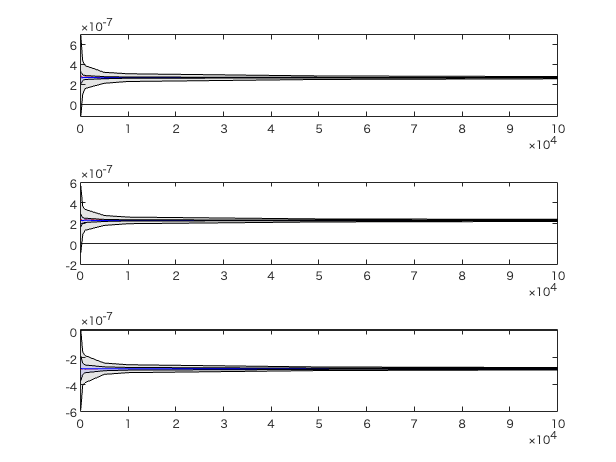

figure
tiledlayout(3,1), nexttile
plotStd(nMCintUni, meanTrue(:,1), 3*stdTrue(:,1), 'r'), hold on
plotStd(nMCintImp, meanImp(:,1), 3*stdImp(:,1), 'b', 'b');

nexttile
plotStd(nMCintUni, meanTrue(:,2), 3*stdTrue(:,2)); hold on
plotStd(nMCintImp, meanImp(:,2), 3*stdImp(:,2),'b', 'b');

nexttile
plotStd(nMCintUni, meanTrue(:,3), 3*stdTrue(:,3)); hold on
plotStd(nMCintImp, meanImp(:,3), 3*stdImp(:,3), 'b', 'b');


disp('mean')

mean


[meanTrue(end,:)
    meanImp(end,:)]

ans = 1.0e-06 *

   0.265534040734194   0.225517591081246  -0.282587041079231
   0.266028108275302   0.225866875774745  -0.282888471277222



disp('standrad deviation')

standrad deviation


[stdTrue(end,:)
    stdImp(end,:)]

ans = 1.0e-08 *

   0.378782723171774   0.337186152562464   0.290992371874568
   0.065862056108237   0.063874755476677   0.103620515002626
